# Math420 - Group Homework 6

Authors: Robert 'Eddie' Bull, Thokozani Tembo

clearvars
disp('With exact distances:')

With exact distances:


rho = 4.4414e+07

upsilon = 1.0e+06 *

    0.3790
    0.5140
    0.8659
    0.3969
    0.6971
    1.6252
    0.6709
    0.6263
    0.0818
    0.1935


G = 1.0e+06 *

    0.3790    0.2326    0.5616    0.1311   -0.1867    0.7848    0.4991   -0.4169    0.1647    0.2595    0.3817    0.3158   -0.2817   -0.4464   -0.0388    0.3384    0.1353    0.2476    0.5607   -0.5613   -0.2864    0.2003   -0.0206    0.3056   -0.0256   -0.1091    0.3050   -0.0805   -1.1033    0.2075    0.0126    0.1588    0.0071    0.1537   -0.0452    0.6744   -0.1275    0.0948    0.6176   -0.8758   -0.2258    0.4342   -0.9830    0.4886    0.0542   -0.6890   -1.1674   -0.8912   -0.7210    0.0847
    0.2326    0.5140    0.4566    0.4418   -0.5886    0.4729    0.2353   -0.5054    0.0395    0.2359    0.2130    0.2370    0.1088   -0.4421   -0.1335    0.1411    0.2177    0.1446    0.4040   -0.9835    0.2626    0.1699    0.3822    0.7392    0.0345   -0.0640    0.1087    0.2125   -0.7579    0.2493    0.2647   -0.0373   -0.2681    0.3247    0.4768    0.4927   -0.2032    0.0318    0.4726   -0.4778   -0.4903    0.2939   -1.3498    0.6060    0.1106   -0.7713   -1.0756   -1.3862   -

10 largest Eigenvalues: 35808397.8081
8605365.07493
0.00535865514396
0.00492317735316
0.00465742835715
0.00398838253825
0.00369384009949
0.00339200997118
0.00270777099669
0.00263403175533


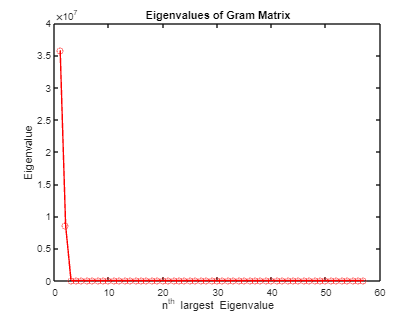

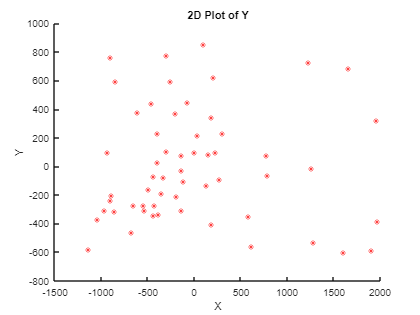

R - R_hat norm for d = 2 is: 5.3218e-06
Epsilon for d = 2 is: 0.018329
Little Sigma for d = 2 is: 0.018329


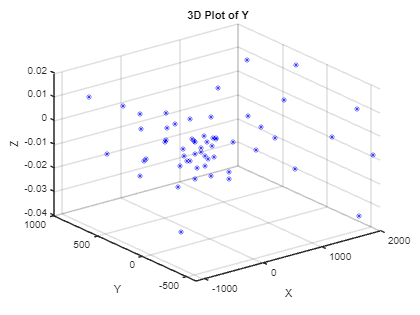

R - R_hat norm for d = 3 is: 1.3649e-05
Epsilon for d = 3 is: 0.017528
Little Sigma for d = 3 is: 0.017528


Y_clean = 1.0e+03 *

   -0.5510   -0.6099   -0.8984   -0.4550    0.6183   -1.1346   -0.6736    0.7887   -0.1943   -0.4333   -0.5394   -0.4907    0.2034    0.7720    0.1367   -0.4433   -0.2952   -0.3546   -0.8590    1.2837    0.0955   -0.3256   -0.2591   -0.8480    0.0004    0.1565   -0.3860   -0.0747    1.6631   -0.3909   -0.2064   -0.1323    0.1891   -0.3921   -0.3036   -1.0382    0.2768   -0.1185   -0.9664    1.2295    0.5857   -0.6514    1.9755   -0.9344   -0.1354    1.2567    1.9601    1.9099    1.6078   -0.1387
   -0.2745    0.3769   -0.2424    0.4358   -0.5611   -0.5814   -0.4659   -0.0644   -0.2098   -0.0754   -0.3078   -0.1652    0.6179    0.0763   -0.1331   -0.3429    0.0999   -0.1901   -0.3182   -0.5322    0.8514   -0.0761    0.5950    0.5890    0.0923    0.0834   -0.3362    0.4430    0.6805    0.0290    0.3685   -0.3130   -0.4055    0.2271    0.7739   -0.3727   -0.0911   -0.1074   -0.3099    0.7222   -0.3530   -0.2742   -0.3846    0.0959    0.0743   -0.0129    0.3180   -0.58


R_exact= readmatrix('Nodes1thru57_dist_exact.txt');
S_exact = R_exact.^2;
n_exact = size(R_exact, 1);
[~,~,~,Y_clean] = algo_1(R_exact, S_exact, n_exact)


disp('With rounded distances:')

With rounded distances:


rho = 4.4427e+07

upsilon = 1.0e+06 *

    0.3731
    0.5105
    0.8498
    0.3993
    0.7023
    1.6290
    0.6896
    0.6301
    0.0677
    0.1860


G = 1.0e+06 *

    0.3731    0.2099    0.5554    0.1234   -0.2004    0.7852    0.5093   -0.3762    0.1512    0.2538    0.3743    0.3086   -0.2915   -0.4418   -0.0398    0.3363    0.1369    0.2393    0.5539   -0.5529   -0.3109    0.1891   -0.0266    0.2859   -0.0233   -0.1093    0.3028   -0.0858   -1.1218    0.2104    0.0073    0.1429   -0.0090    0.1586   -0.0496    0.6688   -0.1199    0.0961    0.6106   -0.8554   -0.2555    0.4272   -0.9895    0.4690    0.0524   -0.6205   -1.0893   -0.8339   -0.6956    0.0777
    0.2099    0.5105    0.4524    0.4434   -0.5748    0.4866    0.2076   -0.5457    0.0483    0.2452    0.1986    0.2278    0.1395   -0.4629   -0.1260    0.1718    0.2254    0.1454    0.3841   -0.9832    0.2849    0.1709    0.3885    0.7362    0.0286   -0.0771    0.1295    0.2199   -0.6236    0.2578    0.2667    0.0107   -0.2445    0.3295    0.4732    0.4848   -0.2325    0.0170    0.4654   -0.4294   -0.4519    0.2465   -1.3630    0.6115    0.1075   -0.8479   -1.0923   -1.4186   -

10 largest Eigenvalues: 35532557.8765
8924037.54946
975952.652631
570066.797641
526331.606867
307163.985738
220021.718282
183279.620937
159784.485404
118556.269906


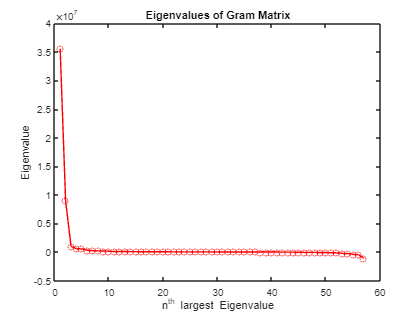

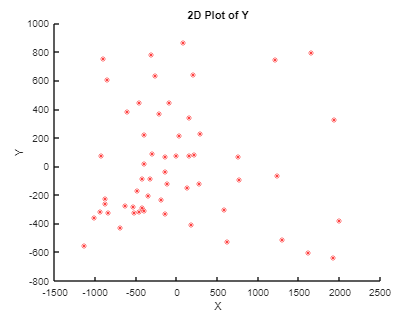

R - R_hat norm for d = 2 is: 1002.8188
Epsilon for d = 2 is: 1927608.6118
Little Sigma for d = 2 is: 1927608.6118


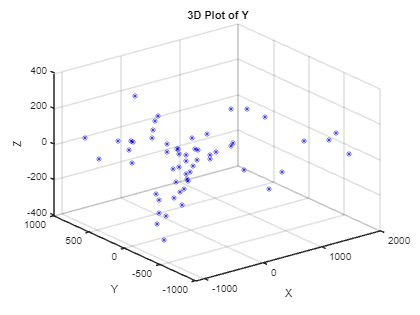

R - R_hat norm for d = 3 is: 1400.6053
Epsilon for d = 3 is: 1662284.9877
Little Sigma for d = 3 is: 1662284.9877


Y_noisy = 1.0e+03 *

   -0.5370   -0.6112   -0.8726   -0.4595    0.6243   -1.1355   -0.6882    0.7757   -0.1868   -0.4246   -0.5237   -0.4791    0.2018    0.7557    0.1348   -0.4557   -0.3023   -0.3428   -0.8340    1.2951    0.0851   -0.3180   -0.2662   -0.8490   -0.0056    0.1506   -0.4016   -0.0925    1.6578   -0.3957   -0.2136   -0.1385    0.1767   -0.3988   -0.3104   -1.0165    0.2765   -0.1139   -0.9418    1.2189    0.5806   -0.6327    2.0038   -0.9274   -0.1381    1.2425    1.9395    1.9197    1.6162   -0.1363
   -0.2849    0.3807   -0.2643    0.4421   -0.5268   -0.5586   -0.4302   -0.0920   -0.2335   -0.0894   -0.3250   -0.1722    0.6431    0.0680   -0.1497   -0.3178    0.0919   -0.2060   -0.3270   -0.5126    0.8662   -0.0874    0.6314    0.6081    0.0756    0.0729   -0.3124    0.4468    0.7930    0.0219    0.3684   -0.3304   -0.4108    0.2213    0.7830   -0.3601   -0.1204   -0.1193   -0.3153    0.7468   -0.3005   -0.2777   -0.3795    0.0772    0.0692   -0.0623    0.3272   -0.63


R_rounded=readmatrix('Nodes1thru57_dist.txt');
S_rounded = R_rounded.^2;
n_rounded = size(R_rounded, 1);
[~,~,~,Y_noisy] = algo_1(R_rounded, S_rounded, n_rounded)


frobenius = @(X) sum(sum(X.^2))^(1/2);
disp('Frobenius norm of (Y_clean - Y_noisy):')

Frobenius norm of (Y_clean - Y_noisy):


frobenius((Y_clean - Y_noisy))

ans = 1.0102e+03

What's interesting is that the epsilon is equal to the little sigma value. This does make sense, though, as we're losing out on the data we aren't calculating, and the Frobenius norm is calculated in a similar way to how we found little sigma.

function [rho, upsilon, G, Y] = algo_1(R, S, n)
    % Use Algorithm 1 to create Gram G
    rho = (1/(2 * n)) * sum(sum(S))
    upsilon = (1/n) *  (S - rho*eye(n)) * ones(n, 1)
    G = 0.5*upsilon*ones(n, 1)' + 0.5*ones(n, 1)*upsilon' - 0.5*S
    
    % Obtain eigenvalues of G
    [Q, V] = eig(G);
    % Get the order index from the sort method
    [E_G, order] = sort(diag(V), 'descend');
    disp('10 largest Eigenvalues: ' + join(string(E_G(1:10)), newline))
    % Resort the Q and V to descending order
    Q = Q(:, order);
    V = V(order, order);
    
    % Plot the Eigenvalues of the Gram Matrix
    figure
    plot(E_G, 'ro-')
    title('Eigenvalues of Gram Matrix')
    ylabel('Eigenvalue')
    xlabel('n^{th} largest Eigenvalue')
    for j=[2 3]
        % Create a Q for the smaller dimensions
        Q_j = Q(:, 1:j);
        V_j = V(1:j, 1:j);
    
        % Compute the Y matrix for each dimension
        Y = V_j.^0.5 * Q_j';
        % When d = 2, it's easier to just plot the function with scatter
        % instead of scatter 3, so condition based on that.
        if j == 2
            figure
            % Scatters the X and Y value of the Y matrix.
            scatter(Y(1, :), Y(2, :), 'r*')
            title('2D Plot of Y')
            ylabel('Y')
            xlabel('X')
        else
            figure
            % Scatters the X, Y, and new Z of Y.
            scatter3(Y(1, :), Y(2, :), Y(3, :), 'b*')
            title('3D Plot of Y')
            ylabel('Y')
            xlabel('X')
            zlabel('Z')
        end
    
        % Pre-allocate for R_hat to increase speed.
        R_hat = zeros(n, n);
        for a = 1:n
            for b = 1:n
                % Calculating R_hat based on the Algorithm 2
                R_hat(a, b) = norm(Y(:, a) - Y(:, b), 2);
            end
        end
    
        % Printing out important values
        disp('R - R_hat norm for d = ' + string(j) + ' is: ' + string(norm(R - R_hat, 2)))
        disp('Epsilon for d = ' + string(j) + ' is: ' + norm(G - Y' * Y, 'fro'))
        disp('Little Sigma for d = ' + string(j) + ' is: ' + sqrt(sum(E_G(j+1:n).^2)))
    end
end